## Zadanie 2) Optymalizacja regulatora PID

Na podstawie pomiarów odpowiedzi układu sterowania na skok jednostkowy wartości referencyjnej należy wykonać optymalizację nastaw regulatora wg krzywej narastania Gk(s) wartości wyjścia z obiektu sterowanego, wykorzystując optymalizację:

Warunek początkowy x0 = [0,0,0],  gdzie x0 = [Kp,Ki,Kd], estymowane Kp=x(1), Ki=x(2),  Kd=x(3)

Należy wykorzystać funkcję Matlaba C = pid(Kp,Ki,Kd) równanie reg w formie operatorowej

gdzie:

clear all
global G1
global t
G1=tf([0 1], [1 2 2.25 1.25]) % obiekt sterowania

G1 =
 
               1
  ---------------------------
  s^3 + 2 s^2 + 2.25 s + 1.25
 
Continuous-time transfer function.



Gk = tf([0 2], [1, 2, 2]) % model Gk

Gk =
 
        2
  -------------
  s^2 + 2 s + 2
 
Continuous-time transfer function.



t = 0:0.01:20;
%C = pid(x(1),x(2),x(3))         % optymalizowany kontroler

#### a)    Optymalizacja genetyczna

Wykorzystując funkcje fminsearch, należy wykonać optymalizację nastaw regulatora PID tak, aby odpowiedź układu regulacji na zmianę wartości referencyjnej - skok jednostkowy była zbliżona do dynamiki modelu Gk(s) (dominująca stała czasowa τ≈1.25[s])

                       2

Gk(s) = -------------------

              s^2 + 2 s + 2

x0 = [0,0,0]

x0 =      0     0     0     0



Single objective optimization:
4 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100           83.86       6.424e+28        0
    2              147           83.86       1.347e+28        1
    3              194           83.86           106.2        2
    4              241           83.04           535.7        0
    5              288           70.34           258.7        0
    6              335           70.14             114        0
    7              382           69.25           80.44        0
    8              429           68.52       1.981e+08        0
    9              476           68.33       1.981e+08        0
   10              523           67.55       1.981e+08        0
   11      

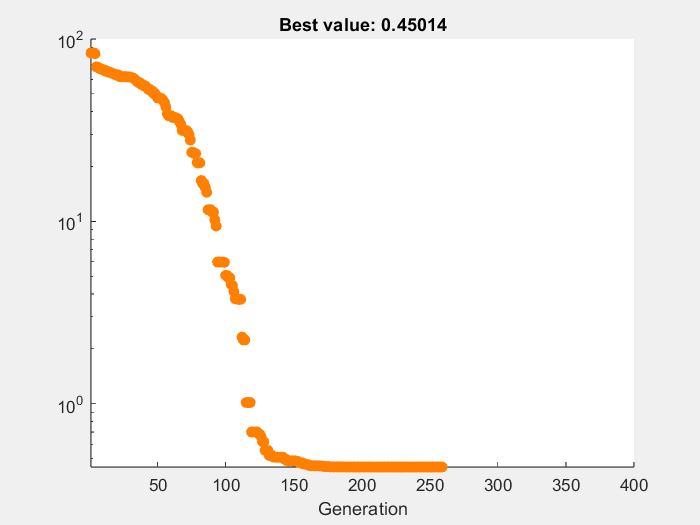

fun = @ident;
%------
A = []; % No other constraints
b = [];
Aeq = [];
beq = [];
lb = [0, 0, 0];
ub = [100, 100, 100];
nonlcon = [];
intcon = [];
options = optimoptions("ga",'PlotFcn', @gaplotchange, 'Display','iter');
options.InitialPopulationMatrix = x0;
[x, fval, exitflag] = ga(fun, 3, A, b, Aeq, beq, lb, ub, nonlcon, intcon, options);

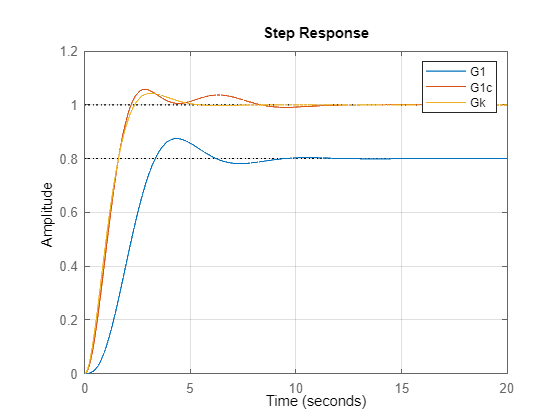


reg=pid(x(1), x(2), x(3));

G1c = feedback(reg*G1, 1);
Gk = tf([0 2], [1, 2, 2]);

figure;
step(G1 ,G1c, Gk, t);
legend(["G1", "G1c", "Gk"]);
grid on;

function blad = ident(x)
global G1 
global t

Gk = tf([0 2], [1, 2, 2]);

reg = pid(x(1), x(2), x(3));

G1c = feedback(reg*G1, 1);

[y1] = step(Gk, t); % wzor
[y2] = step(G1c, t); % dopasowanie

e = y1-y2;
blad = sum(e.^2);

end %ident

function state = gaplotchange(options, state, flag)
persistent last_best
if(strcmp(flag,'init'))
xlim([1,options.MaxGenerations]);
axx = gca;
axx.YScale = 'log';
hold on;
xlabel Generation
X = sprintf('Best value: %.5f', min(state.Score));
title(X)
end
X = sprintf('Best value: %.5f', min(state.Score));
title(X)
best = min(state.Score);
plot(state.Generation,best,'o', 'MarkerFaceColor',[1 0.5 0], ...
'MarkerEdgeColor', [1 0.5 0]);
end
